*Use the Live Editor to ****edit**** and ****run**** this live script in your browser or *[*download*](https://www.mathworks.com/live_editor_integration)* and run it in your MATLAB.*

## 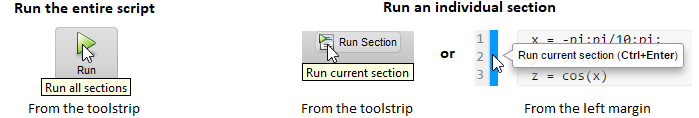

***Challenge:**** Can you find the value of the definite integral *$\int\limits_{0}^{2\pi}sin^2(x)\;cos^2(x)\;dx$ ?

# Integration

This example shows how to compute definite integrals using Symbolic Math Toolbox™.

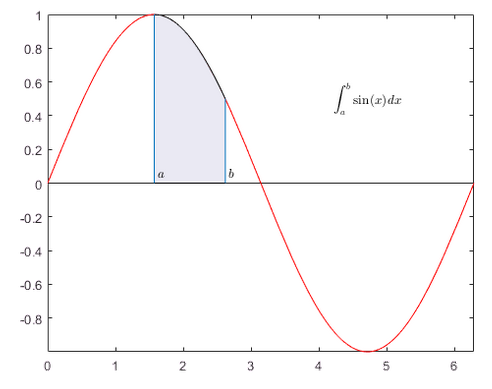

## Definite Integral

The value of the he definite integral $\int\limits_{0}^{2\pi}sin(x)dx$ is 0.

syms x
int(sin(x), 0, 2*pi)

$$ans = 0$$

## Definite Integrals in Maxima and Minima

To maximize $F(a)=\int_{-a}^{a}\sin(ax)\sin(x/a)\,dx$ for $a \geq 0$, first, define the symbolic variables and assume that $a\geq 0$:

syms a x
assume(a >= 0);

Then, define the function to maximize:

F = int(sin(a*x)*sin(x/a),x,-a,a)

$$F = \left\{ \begin{array}{cl} 1-\frac{\sin\left(2\right)}{2} & \text{ if }a=1\\ \frac{2\,a\,\left(\sin\left(a^{2}\right)\,\cos\left(1\right)-a^{2}\,\cos\left(a^{2}\right)\,\sin\left(1\right)\right)}{a^{4}-1} & \text{ if }a\neq 1 \end{array}\right.$$

Note the special case here for $a=1$. To make computations easier, use `assumeAlso` to ignore this possibility.

assumeAlso(a ~= 1);
F = int(sin(a*x)*sin(x/a),x,-a,a)

$$F = \frac{2\,a\,\left(\sin\left(a^{2}\right)\,\cos\left(1\right)-a^{2}\,\cos\left(a^{2}\right)\,\sin\left(1\right)\right)}{a^{4}-1}$$

Create a plot of $F$ to check its shape:

fplot(F,[0 10])

Use `diff` to find the derivative of $F$ with respect to $a$.  The zeros of $Fa$ are the local extrema of $F$.

Fa = diff(F,a)

$$Fa = \begin{array}{l} \frac{2\,\sigma_{1}}{a^{4}-1}+\frac{2\,a\,\left(2\,a\,\cos\left(a^{2}\right)\,\cos\left(1\right)-2\,a\,\cos\left(a^{2}\right)\,\sin\left(1\right)+2\,a^{3}\,\sin\left(a^{2}\right)\,\sin\left(1\right)\right)}{a^{4}-1}-\frac{8\,a^{4}\,\sigma_{1}}{{\left(a^{4}-1\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(a^{2}\right)\,\cos\left(1\right)-a^{2}\,\cos\left(a^{2}\right)\,\sin\left(1\right) \end{array}$$

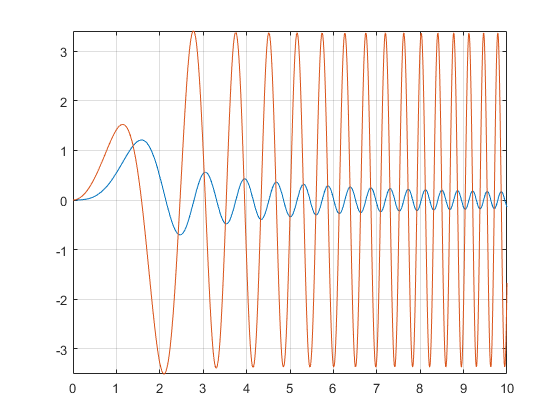

hold on
fplot(Fa,[0 10])
grid on

The maximum is between 1 and 2. Use `vpasolve` to find an approximation of the zero of $Fa$ in this interval:

a_max = vpasolve(Fa,a,[1,2])

$$a\_max = 1.5782881585233198075558845180583$$

Use `subs` to get the maximal value of the integral:

F_max = subs(F,a,a_max)

$$F\_max = 0.36730152527504169588661811770092\,\cos\left(1\right)+1.2020566879911789986062956284113\,\sin\left(1\right)$$

## Multiple Integration

Numerical integration over higher dimensional areas has special functions:

integral2(@(x,y) x.^2-y.^2,0.5,1,0,1)

ans = 0.1250

There are no such special functions for higher-dimensional symbolic integration. Use nested one-dimensional integrals instead:

syms x y
int(int(x^2-y^2,y,0,1),x,0,1)

$$ans = 0$$

## Line Integrals

Define a vector field `F` in 3D space:

syms x y z
F(x,y,z) = [x^2*y*z, x*y, 2*y*z];

Next, define a curve:

syms t
ux(t) = sin(t);
uy(t) = t^2-t;
uz(t) = t;

The line integral of `F` along the curve `u` is defined as $\int f\cdot du = \int f(ux(t),uy(t),uz(t))\cdot \frac{du}{dt}\,dt$, where the $\cdot$ on the right-hand-side denotes a scalar product. 

Use this definition to compute the line integral for $t$ from $[0,1]$

F_int = int(F(ux,uy,uz)*diff([ux;uy;uz],t),t,0,1)

$$F\_int = \frac{19\,\cos\left(1\right)}{4}-\frac{\cos\left(3\right)}{108}-12\,\sin\left(1\right)+\frac{\sin\left(3\right)}{27}+\frac{395}{54}$$

Get a numerical approximation of this exact result:

vpa(F_int)

$$ans = -0.20200778585035447453044423341349$$